# GP-UKF static ver. (GP-UKFとUKFを同時に回してcompareする)

sat-obs-Sun position is fixed and satPos is origin.

軌道運動はとりあえず考えない

GPUKFの入力にmApp_pastMean を追加

clc
clear

### add path for functions

curdir = pwd;
addpath(genpath(strcat(curdir, '/../../hara_functions/')));
addpath(genpath(strcat(curdir, '/../../yoshimuLibrary/'))); % genpathでサブディレクトリ以下全てのpathを取得
addpath(strcat(curdir, '/../../gpryui/'));

% create directory
% mkdir ../results/GPUKF_staticFixed/

tStart = tic;

### constants

earthVSOP = vsopConst; % VSOP parameters
const = orbitConst; % constants for orbital motion

### simulation conditions

model = "boxWing"; % flatPlate or boxWing
trainMethod = "_lcAtti_static";
observation = 'mag'; % light curve magnitude or its inverse value

% random number generator
rng(2022, 'twister');

### load true value and set noise

onjName_lcAtti_static.mat = ['t_', 'mApp', 'q', 'phi', 'theta', 'psi', 'w', 'sat', 'satPos', 'obsPos', 'sunPos']

% load true value
fName = strcat(model, trainMethod, ".mat")

fName = "boxWing_lcAtti_static.mat"

trueData = load(fName); % [t_, mApp, q, phi, theta, psi, w, sat, satPos, obsPos, sunPos]


sat_true = trueData.sat; % 真値の表面特性
sat_u = trueData.sat; % UKFに用いる表面特性 
sat_u.Ca = 0.0;
sat_u.Cd = 0.5; % AS model の rho
sat_u.Cs = 0.5;

t_ = trueData.t_;
tn_ = size(t_, 1);

% set noise
sigTrue = 0.05;
% sigTrue = 0.1; % standard deviation of observation noise
Rtrue = sigTrue^2; % observation noise variance for relative magnitude

### UKF parameters

わからん

n_ = 3; % # of state variable := [error GRP] or [error GRP and angular rate]

% UKF Parameters
ukfPara.alp = 1e-4;
ukfPara.beta = 2;
ukfPara.kap = 3 - n_;% わからん
ukfPara.lam = ukfPara.alp^2 * (n_ + ukfPara.kap) - n_;
ukfPara.lam = 0; % わからん：上書きしてね？

ukfPara.w0m = ukfPara.lam / (n_ + ukfPara.lam); % for mean
ukfPara.wim = 1 / (2 * (n_ + ukfPara.lam));
ukfPara.w0c = ukfPara.lam / (n_ + ukfPara.lam) + (1 - ukfPara.alp^2 + ukfPara.beta); % for covariance
ukfPara.wic = ukfPara.wim;

ukfPara.w0m + 2*3*ukfPara.wim

ans = 1

ukfPara.w0c + 2*3*ukfPara.wic

ans = 4.0000


% estimated obsevation noise (standard deviation)
if strcmp(observation, 'mag')
    sigEst = 3 * sigTrue;
    Rest = sigEst.^2; % measurement noise
    Qest = 0 * deg2rad(1e-2)^2 .* eye(3); % process noise
else
    sigEst = 1e-8;
    Rest = sigEst.^2;
    Qest = 0 * deg2rad(1e-2)^2 .* eye(3); % process noise
end

### pre-allocation

% for GP-UKF
xEst_gu = zeros(tn_, n_); % := [error GRP, angular rate]
Pdiag_gu = zeros(tn_, n_); % diagonal components of covariance matrix (Pcov)
qGlobal_gu = zeros(tn_, 4);
wGlobal_gu = zeros(tn_, 3);
mApp_pastMean = zeros(tn_, 1);
% for UKF
xEst_u = zeros(tn_, n_); % := [error GRP, angular rate]
Pdiag_u = zeros(tn_, n_); % diagonal components of covariance matrix (Pcov)
qGlobal_u = zeros(tn_, 4);
wGlobal_u = zeros(tn_, 3);


ye_gu = zeros(tn_, 1); % GPUKFの予測値
ye_lc_gpAtti = zeros(tn_, 1); % GPUKFの姿勢に対してlc modelを用いた予測値 (for GP modelの精度確認)
ye_u = zeros(tn_, 1); % UKfの予測値

ye0 = 0; % わからん→sigma pointの中心？
yez = zeros(2*n_, 1);
yeOut = zeros(tn_, 1);

% observations
mAppNoise = trueData.mApp + sigTrue .* randn(tn_, 1); % true obs. (relative magnitude), gaussian distribution
dTmp = vecnorm(trueData.obsPos, 2, 2); % [m], distance between sat and observer
mAppInv = magInv(mAppNoise(:,1), dTmp); % true obs. (relative magnitude inverse)

### initial estimate

% initial estimate
qGlobal_gu(1,:) = trueData.q(1,:); % true initial
qGlobal_u(1,:) = trueData.q(1,:); % true initial
% wGlobal_gu(1,:) = trueData.w(1,:); % true initial
mApp_pastMean(1,1) = trueData.mApp(1,1); % とりあえず真値の初期値をmApp_pastMeanの初期推定値として使う

% large initial error 
iniErr = deg2rad(90);
% qGlobal(1,:) = qMult(4, 1, zyx2q(4, iniErr, iniErr, iniErr), q(1,:));

% small initial error
iniErr_q = deg2rad([-10, 5, -10]); % zyx表記
% iniErr_w = deg2rad([1, 1, 1]); % [rad/s]

qGlobal_gu(1,:) = qMult(4, 1, zyx2q(4, iniErr_q(1,1), iniErr_q(1,2), iniErr_q(1,3)), trueData.q(1,:));
qGlobal_u(1,:) = qMult(4, 1, zyx2q(4, iniErr_q(1,1), iniErr_q(1,2), iniErr_q(1,3)), trueData.q(1,:));
% wGlobal(1,:) = wGlobal(1,:) + [iniErr_w(1), iniErr_w(2), iniErr_w(3)];

#### initial covariance for 3$\sigma
$ bound

Pdiag_gu(1,:) = (iniErr ./ 3).^2 .* ones(1, 3);
% Pdiag_gu(1,:) = (iniErr_q ./ 3).^2;
Pdiag_u(1,:) = (iniErr ./ 3).^2 .* ones(1, 3);
% p(1,:) = ([iniErr_q, iniErr_w] ./ 3).^2;
Pcov_gu = diag(Pdiag_gu(1,:));
Pcov_u = diag(Pdiag_u(1,:));

% x:= [error GRP, angular rate]
xEst_gu(1,:) = zeros(1, n_); % わからん→誤差GRPは毎回0にする．？
xEst_u(1,:) = zeros(1, n_);

#### initial obsevation step

load('constGP.mat'); % [x_train, y_train, y_train_mean, K_Dp, Kinv_Dp, K_Do, Kinv_Do, params]

[ye_gu(1,1), ~] = gprNormal([qGlobal_gu(1,:), trueData.satPos(1,:), trueData.obsPos(1,:), trueData.sunPos(1,:), mApp_pastMean(1,1)], x_train, y_train, params, Kinv_Do); 
ye_gu(1,1) = ye_gu(1,1) + y_train_mean(1,1);

nu = 1; % sunlit?, earth shadowing?
ye_lc_gpAtti(1,1) = lc(sat_true, 4, qGlobal_gu(1,:), trueData.satPos(1,:), trueData.obsPos(1,:), trueData.sunPos(1,:), nu, 'AS');

ye_u(1,1) = lc(sat_u, 4, qGlobal_u(1,:), trueData.satPos(1,:), trueData.obsPos(1,:), trueData.sunPos(1,:), nu, 'AS');

### Generalized Rodrigues parameters

aGRP = 1;
fGRP = 2 * (aGRP + 1);

### GP-UKF

% load('constGP.mat'); % [x_train, y_train, y_train_mean, K_Dp, Kinv_Dp, K_Do, Kinv_Do, params]
% filter = "GPUKF" % "GPUKF" or "UKF"

for i = 1:tn_-1
    dt_ = t_(i+1) - t_(i);
    [qGlobal_gu(i+1, :), wGlobal_gu(i+1, :), Pcov_gu, Pdiag_gu(i+1,:), qGlobal_u(i+1,:), wGlobal_u(i+1,:), Pcov_u, Pdiag_u(i+1,:), ye_gu(i+1,1), ye_lc_gpAtti(i+1,1), ye_u(i+1,1), mApp_pastMean(i+1)] = lcGPUKF_cmp_staticFixedPastMean(dt_, xEst_gu(i, :), xEst_u(i,:), Pcov_gu, Pcov_u, mAppNoise(i+1), ...
        ukfPara, Qest, Rest, fGRP, aGRP, qGlobal_gu(i, :), qGlobal_u(i,:), trueData.w(i,:), trueData.satPos(i+1,:), trueData.obsPos(i+1,:), trueData.sunPos(i+1,:), mApp_pastMean(i,1), sat_true, sat_u, const, earthVSOP, x_train, y_train, y_train_mean, params, Kinv_Dp, Kinv_Do);

    % [qGlobal(i+1, :), wGlobal(i+1, :), Pcov] = lcGPUKF_staticFixed(dt_, xEst(i, :), Pcov, mAppNoise(i+1), ...
    %     ukfPara, Qest, Rest, fGRP, aGRP, qGlobal(i, :), wGlobal(i,:), trueData.satPos(i+1,:), trueData.obsPos(i+1,:), trueData.sunPos(i+1,:), trueData.sat, const, earthVSOP, x_train, y_train, y_train_mean, params, Kinv_Dp, Kinv_Do);
end

### just propagate with initial estimated value

初期推定値を用いてそのままpropagate

options = odeset('RelTol',1e-9,'AbsTol',1e-9);
xIni_ode = [trueData.q(1,:), trueData.w(1,:)];
[t_, x_propagated] = ode45(@(t,x)eomAtti_h(t,x,sat_u), t_, xIni_ode, options);
q_propagated = x_propagated(:,1:4);
w_propagated = x_propagated(:,5:7);

### data handling

% 真値と推定値の誤差を出力して精度を確認
% GPUKF
zyx_gu = q2zyx(4, qGlobal_gu);
phi_gu = zyx_gu(:,1);
theta_gu = zyx_gu(:,2);
psi_gu = zyx_gu(:,3);

qe_gu = qErr(4, trueData.q, qGlobal_gu); % error against the true values
zyxE_gu = q2zyx(4, qe_gu);
phiE_gu = zyxE_gu(:,1);
thetaE_gu = zyxE_gu(:,2);
psiE_gu = zyxE_gu(:,3);

we_gu = wGlobal_gu - trueData.w;

yee_gu = ye_gu - ye_lc_gpAtti;

% UKF
zyx_u = q2zyx(4, qGlobal_u);
phi_u = zyx_u(:,1);
theta_u = zyx_u(:,2);
psi_u = zyx_u(:,3);

qe_u = qErr(4, trueData.q, qGlobal_u); % error against the true values
zyxE_u = q2zyx(4, qe_u);
phiE_u = zyxE_u(:,1);
thetaE_u = zyxE_u(:,2);
psiE_u = zyxE_u(:,3);

we_u = wGlobal_u - trueData.w;

% 真値
zyx_true = q2zyx(4, trueData.q);
phi_true = zyx_true(:,1);
theta_true = zyx_true(:,2);
psi_true = zyx_true(:,3);

% 初期推定値からそのままpropageteしたもの
zyx_propagated = q2zyx(4, q_propagated);
phi_propagated = zyx_propagated(:,1);
theta_propagated = zyx_propagated(:,2);
psi_propagated = zyx_propagated(:,3);

## show figures

resultDirName = "GPUKF_cmp_staticFixed"

resultDirName = "GPUKF_cmp_staticFixed"

- GPUKF

% GPUKF ------------
filter = "GPUKF";
dirName = strcat("../results/", resultDirName, "/", filter, "_staticFixed/"); % 絶対パスにすると，同じdirが2つできてしまうので
mkdir(dirName);

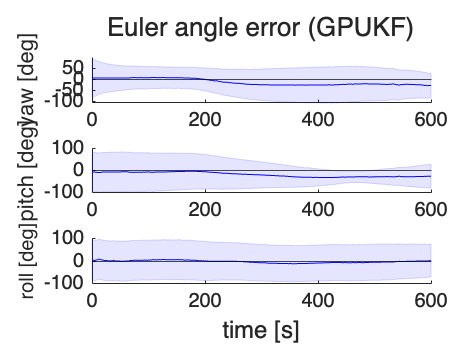

savedir = strcat(curdir, "/", dirName);

figname = "errorQuaternion";
figure('Name', strcat(figname), 'Visible','off');
tile = tiledlayout(4, 1);
nexttile
plot(t_, qe_gu(:,1), 'r');
yline(0, '-k');
xlim([0 t_(end,1)])
title(strcat('error quaternion (', filter, ')'));
nexttile;
plot(t_, qe_gu(:,2), 'g');
yline(0, '-k');
xlim([0 t_(end,1)])
nexttile;
plot(t_, qe_gu(:, 3), 'b');
yline(0, '-k');
xlim([0 t_(end,1)])
nexttile;
plot(t_, qe_gu(:, 4), 'm');
yline(0, '-k');
xlim([0 t_(end,1)])
savename = strcat(savedir, figname, '.pdf');
exportgraphics(gcf, savename);
savename = strcat(savedir, figname, '.jpg');
exportgraphics(gcf, savename);

figname = "eulerAngleError";
figure('Name', figname);
tile = tiledlayout(3,1, 'TileSpacing','Compact');
nexttile
phiE_gu_cov1 = rad2deg(phiE_gu + 3.*sqrt(Pdiag_gu(:,1)));
phiE_gu_cov2 = rad2deg(phiE_gu - 3.*sqrt(Pdiag_gu(:,1)));
p_u_cov = patch([t_', fliplr(t_')], [phiE_gu_cov1', fliplr(phiE_gu_cov2')], 'b', 'FaceAlpha', 0.1, 'EdgeColor', 'b', 'EdgeAlpha', 0.15); % 分散
hold on;
plot(t_, rad2deg(phiE_gu), 'b');
% hold on;
% plot(t_, rad2deg(phiE_gu + 3.*sqrt(Pdiag_gu(:,1))), 'b--');
% hold on;
% plot(t_, rad2deg(phiE_gu - 3.*sqrt(Pdiag_gu(:,1))), 'b--');
hold off;
yline(0, '-k');
xlim([0 t_(end,1)]);
% ylim([-30 30]);
ylabel("yaw [deg]");

nexttile
thetaE_gu_cov1 = rad2deg(thetaE_gu + 3.*sqrt(Pdiag_gu(:,2)));
thetaE_gu_cov2 = rad2deg(thetaE_gu - 3.*sqrt(Pdiag_gu(:,2)));
p_u_cov = patch([t_', fliplr(t_')], [thetaE_gu_cov1', fliplr(thetaE_gu_cov2')], 'b', 'FaceAlpha', 0.1, 'EdgeColor', 'b', 'EdgeAlpha', 0.15); % 分散
hold on;
plot(t_, rad2deg(thetaE_gu), 'b');
hold off;
yline(0, '-k');
xlim([0 t_(end,1)]);
ylabel("pitch [deg]");

nexttile
psiE_gu_cov1 = rad2deg(psiE_gu + 3.*sqrt(Pdiag_gu(:,3)));
psiE_gu_cov2 = rad2deg(psiE_gu - 3.*sqrt(Pdiag_gu(:,3)));
p_u_cov = patch([t_', fliplr(t_')], [psiE_gu_cov1', fliplr(psiE_gu_cov2')], 'b', 'FaceAlpha', 0.1, 'EdgeColor', 'b', 'EdgeAlpha', 0.15); % 分散
hold on;
plot(t_, rad2deg(psiE_gu), 'b');
hold off;
yline(0, '-k');
xlim([0 t_(end,1)]);
ylabel("roll [deg]", 'FontSize', 10);
xlabel(tile, "time [s]")
title(tile, strcat('Euler angle error (', filter, ')'));
savename = strcat(savedir, figname, '.pdf');
exportgraphics(gcf, savename);
savename = strcat(savedir, figname, '.jpg');
exportgraphics(gcf, savename);


% figname = "angularVelocityError";
% figure('Name', figname)
% tiledlayout(3,1), nexttile
% plot(t_, rad2deg(we_gu(:,1)), 'r'); 
% yline(0, '-k');
% title(strcat('Angular velocity error [deg/s] (', 'filter', ')'));
% xlim([0 t_(end,1)])%, ylim([-60 60])
% nexttile
% plot(t_, rad2deg(we_gu(:,2)), 'g');
% yline(0, '-k');
% xlim([0 t_(end,1)])%, ylim([-60, 60]);
% nexttile
% plot(t_, rad2deg(we_gu(:,3)), 'b');
% yline(0, '-k');
% xlim([0 t_(end,1)])%, ylim([-60 60]);
% savename = strcat(savedir, figname, '.pdf');
% exportgraphics(gcf, savename);
% savename = strcat(savedir, figname, '.jpg');
% exportgraphics(gcf, savename);

- UKF

% UKF ------------
filter = "UKF";
dirName = strcat("../results/", resultDirName, "/", filter, "_staticFixed/"); % 絶対パスにすると，同じdirが2つできてしまうので
mkdir(dirName);

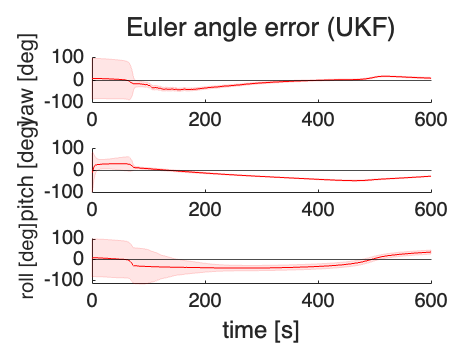

savedir = strcat(curdir, "/", dirName);

figname = "errorQuaternion";
figure('Name', strcat(figname), 'Visible','off');
tile = tiledlayout(4, 1);
nexttile
plot(t_, qe_u(:,1), 'r');
yline(0, '-k');
xlim([0 t_(end,1)])
title(strcat('error quaternion (', filter, ')'));
nexttile;
plot(t_, qe_u(:,2), 'g');
yline(0, '-k');
xlim([0 t_(end,1)])
nexttile;
plot(t_, qe_u(:, 3), 'b');
yline(0, '-k');
xlim([0 t_(end,1)])
nexttile;
plot(t_, qe_u(:, 4), 'm');
yline(0, '-k');
xlim([0 t_(end,1)])
savename = strcat(savedir, figname, '.pdf');
exportgraphics(gcf, savename);
savename = strcat(savedir, figname, '.jpg');
exportgraphics(gcf, savename);


figname = "eulerAngleError";
figure('Name', figname);
tile = tiledlayout(3,1, 'TileSpacing','Compact');
nexttile
phiE_u_cov1 = rad2deg(phiE_u + 3.*sqrt(Pdiag_u(:,1)));
phiE_u_cov2 = rad2deg(phiE_u - 3.*sqrt(Pdiag_u(:,1)));
p_u_cov = patch([t_', fliplr(t_')], [phiE_u_cov1', fliplr(phiE_u_cov2')], 'r', 'FaceAlpha', 0.1, 'EdgeColor', 'r', 'EdgeAlpha', 0.15); % 分散
hold on;
plot(t_, rad2deg(phiE_u), 'r-'); 
hold off;
yline(0, '-k');
xlim([0 t_(end,1)]);
% ylim([-30 30]);
ylabel("yaw [deg]");

nexttile
thetaE_u_cov1 = rad2deg(thetaE_u + 3.*sqrt(Pdiag_u(:,2)));
thetaE_u_cov2 = rad2deg(thetaE_u - 3.*sqrt(Pdiag_u(:,2)));
p_u_cov = patch([t_', fliplr(t_')], [thetaE_u_cov1', fliplr(thetaE_u_cov2')], 'r', 'FaceAlpha', 0.1, 'EdgeColor', 'r', 'EdgeAlpha', 0.15); % 分散
hold on;
plot(t_, rad2deg(thetaE_u), 'r');
hold off;
yline(0, '-k');
xlim([0 t_(end,1)]);
% ylim([-30 30]);
ylabel("pitch [deg]");

nexttile
psiE_u_cov1 = rad2deg(psiE_u + 3.*sqrt(Pdiag_u(:,3)));
psiE_u_cov2 = rad2deg(psiE_u - 3.*sqrt(Pdiag_u(:,3)));
p_u_cov = patch([t_', fliplr(t_')], [psiE_u_cov1', fliplr(psiE_u_cov2')], 'r', 'FaceAlpha', 0.1, 'EdgeColor', 'r', 'EdgeAlpha', 0.15); % 分散
hold on;
plot(t_, rad2deg(psiE_u), 'r');
hold off;
yline(0, '-k');
xlim([0 t_(end,1)]);
% ylim([-30 30]);
ylabel("roll [deg]", 'FontSize', 10);
xlabel(tile, "time [s]")
title(tile, strcat('Euler angle error (', filter, ')'));
savename = strcat(savedir, figname, '.pdf');
exportgraphics(gcf, savename);
savename = strcat(savedir, figname, '.jpg');
exportgraphics(gcf, savename);

- both of filters

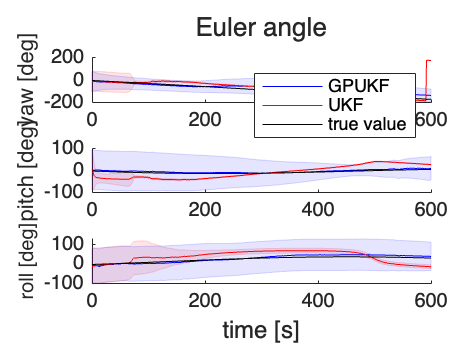

% そのまま比較（not error）--------------
dirName = strcat("../results/", resultDirName, "/"); % 絶対パスにすると，同じdirが2つできてしまうので
% mkdir(dirName);
savedir = strcat(curdir, "/", dirName);

figname = "eulerAngle";
figure('Name', figname);
tile = tiledlayout(3,1, 'TileSpacing','Compact');
nexttile
phi_gu_cov1 = rad2deg(phi_gu + 3.*sqrt(Pdiag_gu(:,1)));
phi_gu_cov2 = rad2deg(phi_gu - 3.*sqrt(Pdiag_gu(:,1)));
phi_u_cov1 = rad2deg(phi_u + 3.*sqrt(Pdiag_u(:,1)));
phi_u_cov2 = rad2deg(phi_u - 3.*sqrt(Pdiag_u(:,1)));
p_u_cov = patch([t_', fliplr(t_')], [phi_u_cov1', fliplr(phi_u_cov2')], 'r', 'FaceAlpha', 0.1, 'EdgeColor', 'r', 'EdgeAlpha', 0.15); % 分散
hold on;
p_gu_cov = patch([t_', fliplr(t_')], [phi_gu_cov1', fliplr(phi_gu_cov2')], 'b', 'FaceAlpha', 0.1, 'EdgeColor', 'b', 'EdgeAlpha', 0.15); % 分散
hold on;
p_gu = plot(t_, rad2deg(phi_gu), 'b');
hold on;
p_u = plot(t_, rad2deg(phi_u), 'r');
hold on;
p_true = plot(t_, rad2deg(phi_true), 'k');
hold on;
% p_propagated = plot(t_, rad2deg(phi_propagated), 'g');
hold off;
% yline(0, '-k');
xlim([0 t_(end,1)])
ylabel("yaw [deg]");
legend([p_gu, p_u, p_true], {'GPUKF', 'UKF', 'true value'})

nexttile
theta_gu_cov1 = rad2deg(theta_gu + 3.*sqrt(Pdiag_gu(:,2)));
theta_gu_cov2 = rad2deg(theta_gu - 3.*sqrt(Pdiag_gu(:,2)));
theta_u_cov1 = rad2deg(theta_u + 3.*sqrt(Pdiag_u(:,2)));
theta_u_cov2 = rad2deg(theta_u - 3.*sqrt(Pdiag_u(:,2)));
p_u_cov = patch([t_', fliplr(t_')], [theta_u_cov1', fliplr(theta_u_cov2')], 'r', 'FaceAlpha', 0.1, 'EdgeColor', 'r', 'EdgeAlpha', 0.15); % 分散
hold on;
p_gu_cov = patch([t_', fliplr(t_')], [theta_gu_cov1', fliplr(theta_gu_cov2')], 'b', 'FaceAlpha', 0.1, 'EdgeColor', 'b', 'EdgeAlpha', 0.15); % 分散
hold on;
p_gu = plot(t_, rad2deg(theta_gu), 'b');
hold on;
p_u = plot(t_, rad2deg(theta_u), 'r');
hold on;
p_true = plot(t_, rad2deg(theta_true), 'k');
hold on;
% p_propagated = plot(t_, rad2deg(theta_propagated), 'g');
hold off;
% yline(0, '-k');
xlim([0 t_(end,1)])
ylabel("pitch [deg]");

nexttile
psi_gu_cov1 = rad2deg(psi_gu + 3.*sqrt(Pdiag_gu(:,3)));
psi_gu_cov2 = rad2deg(psi_gu - 3.*sqrt(Pdiag_gu(:,3)));
psi_u_cov1 = rad2deg(psi_u + 3.*sqrt(Pdiag_u(:,3)));
psi_u_cov2 = rad2deg(psi_u - 3.*sqrt(Pdiag_u(:,3)));
p_u_cov = patch([t_', fliplr(t_')], [psi_u_cov1', fliplr(psi_u_cov2')], 'r', 'FaceAlpha', 0.1, 'EdgeColor', 'r', 'EdgeAlpha', 0.15); % 分散
hold on;
p_gu_cov = patch([t_', fliplr(t_')], [psi_gu_cov1', fliplr(psi_gu_cov2')], 'b', 'FaceAlpha', 0.1, 'EdgeColor', 'b', 'EdgeAlpha', 0.15); % 分散
hold on;
p_gu = plot(t_, rad2deg(psi_gu), 'b');
hold on;
p_u = plot(t_, rad2deg(psi_u), 'r');
hold on;
p_true = plot(t_, rad2deg(psi_true), 'k-');
hold on;
% p_propagated = plot(t_, rad2deg(psi_propagated), 'g');
hold off;
% yline(0, '-k');
xlim([0 t_(end,1)])
ylabel("roll [deg]", 'FontSize', 10);
xlabel(tile, "time [s]")
title(tile, strcat('Euler angle'));
savename = strcat(savedir, figname, '.pdf');
exportgraphics(gcf, savename);
savename = strcat(savedir, figname, '.jpg');
exportgraphics(gcf, savename);


% 観測モデルの回帰精度を可視化 ----------
figname = "observationModelError";
figure('Name', figname)
% t = tiledlayout(2,1), nexttile
p_gu = plot(t_, ye_gu, 'b'); 
hold on;

p_lc_gpAtti = plot(t_, ye_lc_gpAtti, 'g');
hold on;
p_obs = plot(t_, mAppNoise, 'k-');
hold on;
p_obs.Color(4) = 0.5;

p_u = plot(t_, ye_u, 'r');

legendObj = legend([p_gu, p_lc_gpAtti, p_obs, p_u], {'GP model', 'Lc model(GPUKF)', 'Observed values', 'Lc model(UKF)'})

legendObj =   Legend (GP model, Lc model(GPUKF), Observed values, Lc model(UKF)) with properties:

         String: {'GP model'  'Lc model(GPUKF)'  'Observed values'  'Lc model(UKF)'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.6884 0.7881 0.2027 0.1179]
          Units: 'normalized'

  Show all properties


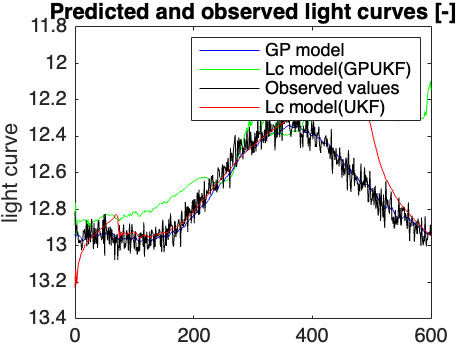

title('Predicted and observed light curves [-]');
xlim([0 t_(end,1)])%, ylim([-60 60])
ylabel("light curve")
set(gca, 'YDir', 'reverse')

% nexttile
% plot(t_, yee_gu, 'g');
% yline(0, '-k');
% xlim([0 t_(end,1)])%, ylim([-60, 60]);
% xlabel("time [s]");
% ylabel("litht curve error between GP model and lc model")

savename = strcat(savedir, figname, '.pdf');
exportgraphics(gcf, savename);
savename = strcat(savedir, figname, '.jpg');
exportgraphics(gcf, savename);

tEnd = toc(tStart) / 60; % [min]
strcat("calculation time [min] : ", num2str(tEnd))

ans = "calculation time [min] : 14.795"